# Example 2

#### Problem OCP:


$$\min_{{x}(t),{u}(t),t_f} \int_0^{t_f} 1 d \tau $$


subject to:


$$
 \dot{{x}}_1(t) = x_3(t), \quad \dot{{x}}_2(t) = x_4(t), \quad   \dot{{x}}_3(t) = u_1(t), \quad \dot{{x}}_4(t) = u_2(t),$$



$${x}_1(0)=-3, \quad x_2(0)=0, \quad {x}_1(t_f)=0, \quad {x}_2(t_f)=0,$$



$$x_3(0) = 0, \quad x_4(0)= 0, \quad x_3(t_f) = 0 , \quad x_4(0) = 0$$



$$ \sqrt{x_3^2+x_4^2} \leq v_{\max}, \quad \sqrt{u_1^2+u_2^2} \leq a_{\max}.$$


## Implementation:

clear all
close all

### Load Parameters

CONSTANTS.N = 10; % Order of approximation
CONSTANTS.amax = 5;
CONSTANTS.amin = -5;
CONSTANTS.vmax = 5;
CONSTANTS.vmin = -5;
CONSTANTS.x0 = [-3, 0, 2, 0];
CONSTANTS.xf = [10, 10, 2, 0];

### Initial Guess

N = CONSTANTS.N; 
%x1 = linspace(CONSTANTS.x0,CONSTANTS.xf,CONSTANTS.N+1)';
x1 = ones(N+1,1);
x2 = ones(N+1,1);
x3 = ones(N+1,1);
x4 = ones(N+1,1);
u1 = ones(N+1,1);
u2 = ones(N+1,1);
tf = 10;
x0 = [x1;x2;x3;x4;u1;u2;tf];

### Linear Constraints and UL bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

### Optimize (fmincon)

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',300000);
tic
[x,f] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 0.552458 seconds.


### Plot

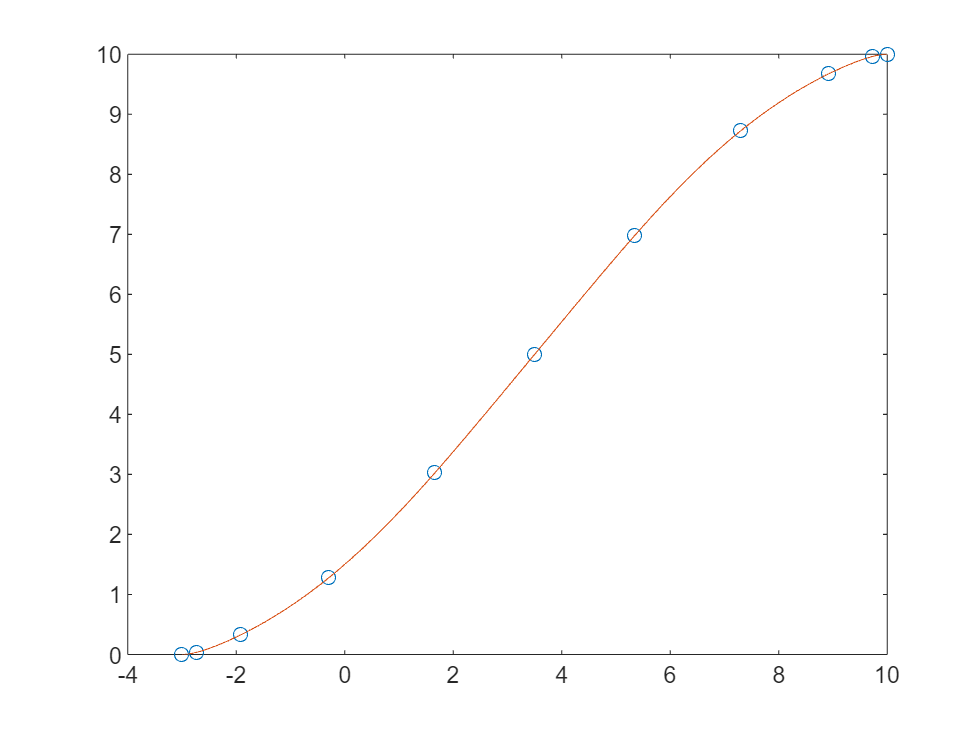

N = CONSTANTS.N;

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
u1 = x(4*N+5:5*N+5);
u2 = x(5*N+6:6*N+6);
tf = x(end);

[tnodes,w,Diff] = LGL_PS(N,tf);
t = linspace(0,tf,1000);

figure
plot(x1,x2,'o'); hold on
plot(LagrangePoly(x1,tnodes,t),LagrangePoly(x2,tnodes,t));

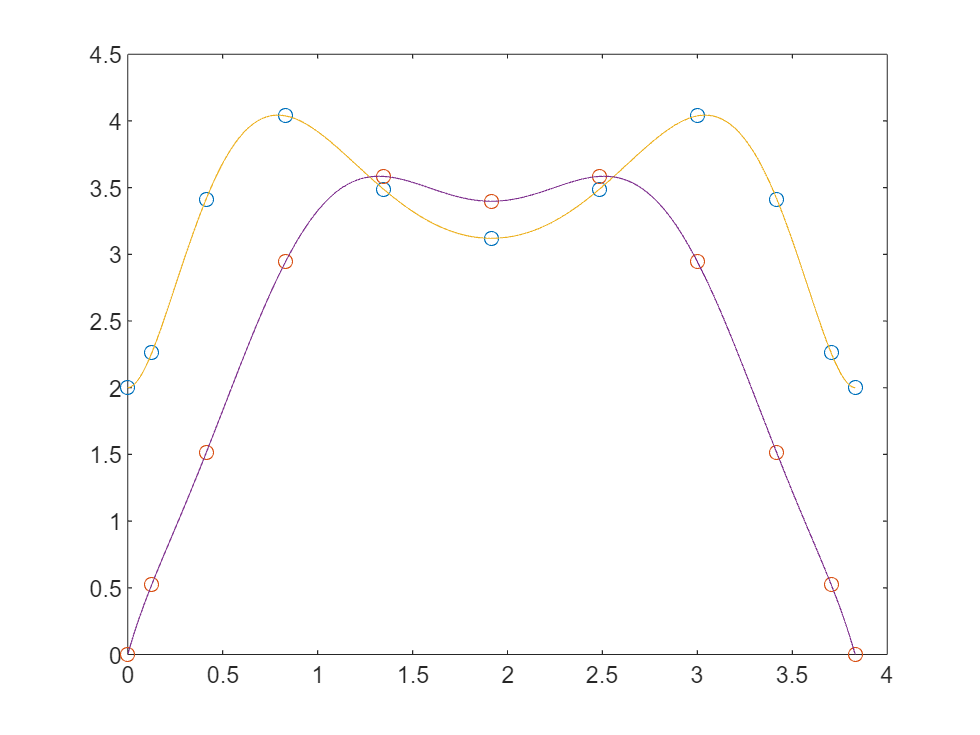


figure
plot(tnodes,x3,'o'); hold on
plot(tnodes,x4,'o');
plot(t,LagrangePoly(x3,tnodes,t));
plot(t,LagrangePoly(x4,tnodes,t));

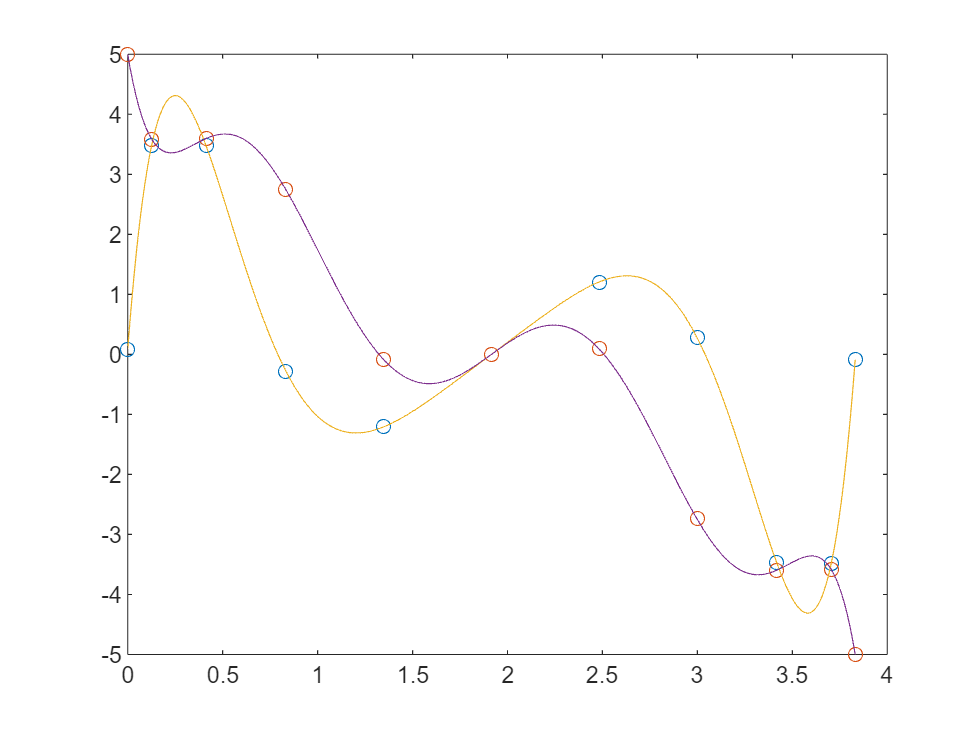


figure
plot(tnodes,u1,'o'); hold on
plot(tnodes,u2,'o');
plot(t,LagrangePoly(u1,tnodes,t));
plot(t,LagrangePoly(u2,tnodes,t));

### Cost function

function J = costfun(x,CONSTANTS)
%COSTFUN Summary of this function goes here
N = CONSTANTS.N; 

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
u1 = x(4*N+5:5*N+5);
u2 = x(5*N+6:6*N+6);
tf = x(end);

J = tf;
end

### Nonlinear Constraint

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N; 

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
x3 = x(2*N+3:3*N+3);
x4 = x(3*N+4:4*N+4);
u1 = x(4*N+5:5*N+5);
u2 = x(5*N+6:6*N+6);
tf = x(end);

[tnodes,w,Diff] = LGL_PS(CONSTANTS.N,tf);

dyn1 = x1'*Diff-x3';
dyn2 = x2'*Diff-x4';
dyn3 = x3'*Diff-u1';
dyn4 = x4'*Diff-u2';

u = sqrt(u1.^2 + u2.^2);
v = sqrt(x3.^2 + x4.^2);

nonlcon1 = u' - CONSTANTS.amax;
nonlcon2 = -u' + CONSTANTS.amin;
nonlcon3 = v' - CONSTANTS.vmax;
nonlcon4 = -v' + CONSTANTS.vmin;

BCinit = [x1(1) - CONSTANTS.x0(1), x2(1) - CONSTANTS.x0(2), ...
          x3(1) - CONSTANTS.x0(3), x4(1) - CONSTANTS.x0(4)];
BCfin = [x1(end) - CONSTANTS.xf(1), x2(end) - CONSTANTS.xf(2), ...
          x3(end) - CONSTANTS.xf(3), x4(end) - CONSTANTS.xf(4)];

c=[nonlcon1'; nonlcon2';nonlcon3'; nonlcon4';];
ceq=[dyn1'; dyn2'; dyn3'; dyn4'; BCinit' ; BCfin'];
end